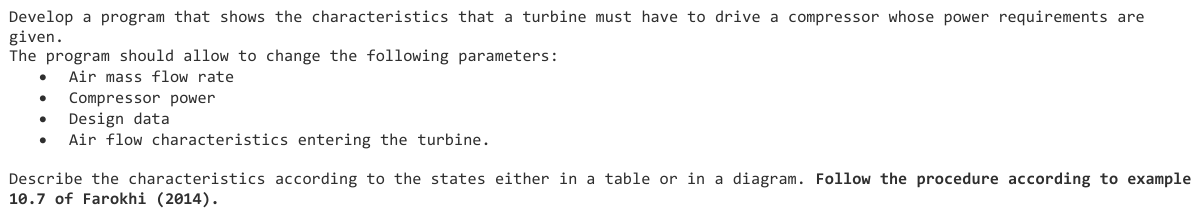

% Turbine i let mass flow rate 
m_1 = 93 %kg/s

m_1 = 93

% Shaft rpm 
w = 8770 %rpm 

w = 8770

% Turbine inlet (total) temperature and pressure 
Tt_1 = 1500 %K 

Tt_1 = 1500

pt_1 = 1500 %kpa

pt_1 = 1500

% Pitchline radius at the compressor inlet
rm_1 = 0.4 %m

rm_1 = 0.4000

% there is a specification that 10 kg/s of air was bled off at the
% compressor exit to provide turbine cooling. 
% The cooling information is thus 
m_c = 10 %kg/s 

m_c = 10

Tt_c = 704 %K 

Tt_c = 704

pt_c = 1500 %kpa 

pt_c = 1500

% The design ambient pressure and temperature and flight Mach number are
% also know, thus we have 
M_0 = 0

M_0 = 0

p_0 = 101 %kpa

p_0 = 101

T_0 = 25 %C

T_0 = 25

T_0k = T_0 + 273.15

T_0k = 298.1500


% gas characteristics 
c_pc = 1004.5 %J/kg*K

c_pc = 1.0045e+03

gma_c = 1.40

gma_c = 1.4000

c_pt = 1243.67 %J/kg*K

c_pt = 1.2437e+03

gma_t = 1.30 %J/kg*K

gma_t = 1.3000

R = 287 

R = 287


% Here we assume that the mechanical efficiency is 0.995. 

eff_m = 0.995

eff_m = 0.9950

m_0 = 100 % kg/s

m_0 = 100

mc = m_c/m_1

mc = 0.1075

compressor_c = m_0*c_pc*(Tt_c - T_0k) % in MW 

compressor_c = 4.0768e+07


% Therefore, the turbine shaft power required is 

turbine_shaft_pwr = compressor_c/eff_m % in MW 

turbine_shaft_pwr = 4.0972e+07


% for a compressor presure ratio of 20 and polytropic efficiency of ec =
% 0.90 

Tt_4 = 1600 % Design choice 

Tt_4 = 1600


Tt_5_cooled = ( (Tt_4*((1-mc)*c_pt)) + (Tt_c*mc*c_pc) - (turbine_shaft_pwr/m_1) )/( ((1-mc)*c_pt) + (mc*c_pc) )

Tt_5_cooled = 1.1588e+03


% first turbine nozzle pitchline design ( Cz )

M_2 = 1.1 % design choice for the 1st turbine nozzle 

M_2 = 1.1000


T_2 = Tt_1 / ( 1 + 0.15*(M_2^2))

T_2 = 1.2696e+03


a2 = (R*gma_c*T_2) ^ 0.5 

a2 = 714.2228


C2 = M_2*a2

C2 = 785.6451


alpha_2 = 60 %degree 

alpha_2 = 60


C_th_2 = sind(alpha_2)*C2

C_th_2 = 680.3886


C_z2 = cosd(alpha_2)*C2

C_z2 = 392.8226


T1 = Tt_1 - ((C_z2^2)/(2*c_pt))

T1 = 1.4380e+03


% thus 

a1 = (T1*R*gma_c) ^ 0.5

a1 = 760.1139


M1 = C_z2/a1

M1 = 0.5168

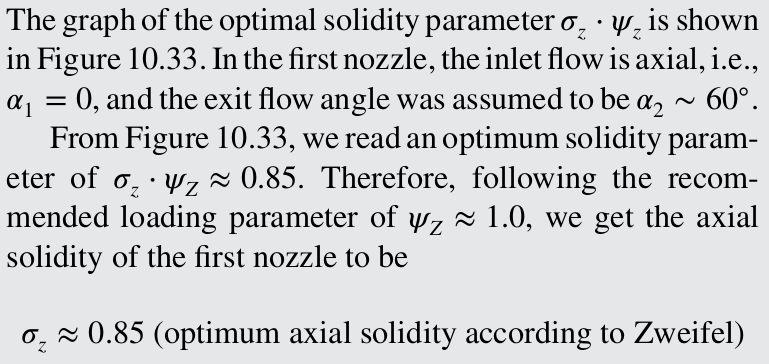

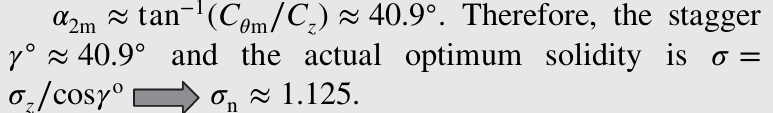

sigma_z = 0.85 

sigma_z = 0.8500

sigma_n = 2

sigma_n = 2


% First turbine nozzle deviation angle 
% since the first nozzle exit Mach number was chosen to be 1.1 we neglect
% the  deviation angle at the first nozzle exit. 

% Fisrt turbine nozzle throat sizing 

o_s = cosd(alpha_2)/0.496 

o_s = 1.0081


% First turbine nozzle cooling 

M_g = (M1 + M_2)/2 

M_g = 0.8084


p_tg = 1500000 

p_tg = 1500000

T_tg = 1500

T_tg = 1500


mass_density = ((gma_t/R)^0.5)*(p_tg/(T_tg)^0.5)*M_g*((1 + 0.15*(M_g^2))^(-3.83))

mass_density = 1.4728e+03


Twg = 1400

Twg = 1400

tw = 1.5 %mm 

tw = 1.5000

kw = 14.9 % W/mK

kw = 14.9000

Stg = 0.005

Stg = 0.0050

Taw = T_tg

Taw = 1500


% thus 

Twc = 1376.9 %K

Twc = 1.3769e+03


% First turbine rotor pitchline design 
% the first rotor rotational speed at the pitchline is 

Um = w*rm_1*(6.28/60)

Um = 367.1707


% For starters we choose M3r = 0.8 

M3r = 0.8 % can go from 0.9 to 0.8 

M3r = 0.8000


W_th2 = C_th_2 - Um 

W_th2 = 313.2180


W_th3 = -((M3r^2*(a2^2 + (gma_t-1)*((W_th2^2)/2))-C_z2^2)/(1+(gma_t-1)*(M3r^2)/2) )^0.5

W_th3 = -407.0341


C_th3 = W_th3 + Um 

C_th3 = -39.8634


W2 = (C_z2^2 + W_th2^2)^0.5

W2 = 502.4093


M2r = W2/C_th_2

M2r = 0.7384


Rm = 1 - (C_th_2+C_th3)/(2*Um) 

Rm = 0.1278


beta2 = atand(W_th2/Um)

beta2 = 40.4661

beta3 = atand(W_th3/Um)

beta3 = -47.9475

alpha3 = atand(C_th3/Um)

alpha3 = -6.1963


Tt_2 = 1500

Tt_2 = 1500


T2 = Tt_2 - (C2^2)/(2*c_pt)

T2 = 1.2518e+03


% therefore 

Tt2r = T2 + (W2^2)/(2*c_pt)

Tt2r = 1.3533e+03


wn = 0.06 

wn = 0.0600


p1 = pt_1 / (( 1 + 0.2*(M1^2))^3.5) 

p1 = 1.2502e+03


% thus 

pt2 = pt_1 - (wn*(pt_1-p1))

pt2 = 1.4850e+03


p2 = pt2 / (( 1 + 0.2*(M_2^2))^3.5)

p2 = 695.5127


Pt2r = p2*(( 1 + 0.2*(M2r^2))^3.5)

Pt2r = 999.1619


Tt3 = (w*(6.28/60)*rm_1*(C_th3-C_th_2) + c_pt*Tt_2)/c_pt

Tt3 = 1.2874e+03


C3 = (C_th3^2 + C_z2^2)^0.5

C3 = 394.8400


T3 = Tt3 - (C3^2)/(2*c_pt)

T3 = 1.2247e+03


a3 = (R*gma_t*T3)^0.5

a3 = 675.9651


M3 = C_z2/a3

M3 = 0.5811


% If we assume a relative total pressure loss coefficient in the rotor wr =
% 0.08 

wr = 0.08 

wr = 0.0800


pt3r = Pt2r - (wr*(Pt2r-p2))

pt3r = 974.8700


p3 = pt3r / (( 1 + 0.15*(M3r^2))^4.3)

p3 = 657.2965


% optimum solidity approach of Zweifel we estimate the axial solidity
% parameter for the first turbine rotor to be 

Solidity_Zweifel = 1.8 

Solidity_Zweifel = 1.8000


sigma_zr = 1.8 

sigma_zr = 1.8000


Wthm = (W_th3+W_th2)/2

Wthm = -46.9080


beta_m = atand(Wthm/C_z2)

beta_m = -6.8096


% therefore 

rotor_solidity = sigma_zr/cosd(beta_m)

rotor_solidity = 1.8128


sigma_r1 = rotor_solidity

sigma_r1 = 1.8128


rotor_deviation_angle = (90-beta_m)/(8*sigma_r1)

rotor_deviation_angle = 6.6755


% First stage loading parameter and shaft power 

w_t = Um*(C_th_2-C_th3)

w_t = 2.6446e+05

phsi = w_t/(Um^2) 

phsi = 1.9616


% The shaft power that the first stage (rotor) produces is 

Pwr_1stage = m_1*(w_t) % in MW 

Pwr_1stage = 2.4594e+07


% The second turbine nozzle pitchline design 

% design choice for alpha 4 = 53 degrees 

alpha4 = 53 % can be adjusted up to 70 or down to 40)

alpha4 = 53


M4 = 0.964 % design choice 

M4 = 0.9640


rm_3 = 0.42 

rm_3 = 0.4200


% for this choices we calculate the second nozzle exit flow conditions, and
% with an assumed total pressure loss parameter of wn2 = 0.06

wn2 = 0.06

wn2 = 0.0600


pt3 = p3*(( 1 + 0.15*(M3^2))^4.3)

pt3 = 812.9103


pt4 = pt3 - (wn2*(pt3-p3))

pt4 = 803.5734


U3 = 385.7 

U3 = 385.7000

W_th_4 = 116.6 

W_th_4 = 116.6000

C_th4 = W_th_4 + Um

C_th4 = 483.7707

beta4 = 17.1 

beta4 = 17.1000

W4 = 396 

W4 = 396

M4r = 0.607 

M4r = 0.6070

pt4r = 553.8 

pt4r = 553.8000


% our choice of the second nozzle solidity sigma_n2 = 0.2 and deviation
% angle of 3.54 degrees 

sigma_n2 = 0.2 

sigma_n2 = 0.2000

dev_angl = 3.54 

dev_angl = 3.5400


o_s_N2 = 0.602 

o_s_N2 = 0.6020


% Second turbine rotor pitchline design 
% The second rotor exit Mach number is a design choice for whicb we have
% chosen 

M5r = 0.85 % always less than 1 

M5r = 0.8500


% the second rotor exit flow condition are 

C5 = 378.5 

C5 = 378.5000

C_th5 = -0.74

C_th5 = -0.7400

alpha5 = -0.1 

alpha5 = -0.1000

M5 = 0.594 

M5 = 0.5940


% Second stage degree of reaction is 

R_2 = 0.350 

R_2 = 0.3500


w_t_2 = Um*(C_th4 - C_th5)

w_t_2 = 1.7790e+05

phsi_2 = w_t_2/Um^2 

phsi_2 = 1.3196


% Shaft power for the second stage (rotor) 

Pwr_2stge = m_1*w_t_2 % in MW

Pwr_2stge = 1.6545e+07


CP = (m_1*c_pt + m_c*c_pc)/(m_1+m_c)

CP = 1.2204e+03


Tt5 = ((Tt_5_cooled*(m_1+m_c)*CP) - (m_c*c_pc*Tt_c))/(m_1*c_pt) % in Kelvins

Tt5 = 1.1983e+03


tao_t = Tt5/Tt_4

tao_t = 0.7489


eff_t = 0.77

eff_t = 0.7700


pi_t = (1 - (1/eff_t)*(1-tao_t))^4.3

pi_t = 0.1833


pt5_cooled = pt4*pi_t % in Kpa

pt5_cooled = 147.2803


% Turbine annulus sizing 

A1 = m_1*((R/gma_t)^0.5)*(((Tt_1)^0.5)/(pt_1*1000))/(M1*((1 + 0.15*(M1^2))^(-3.83))) % in meters squared 

A1 = 0.0802


h1 = A1/(6.28*rm_1)*100 % in cm

h1 = 3.1945


m5 = m_1+m_c

m5 = 103


A5 = m5*((R/gma_t)^0.5)*(((Tt_5_cooled)^0.5)/(pt5_cooled*1000))/(M5*((1 + 0.15*(M5^2))^(-3.83))) % in meter squared 

A5 = 0.7255


h5 = A5/(6.28*rm_3)*100 % in cm 

h5 = 27.5078